## Settings for simulink model initialization and data analysis

close all
clear all
clc
beep off
pm_addunit('percent', 0.01, '1');
options = bodeoptions;
options.FreqUnits = 'Hz';
simlength = 0.5;
transmission_delay = 125e-6*2;
s=tf('s');


### Settings voltage application

application400 = 1;
application690 = 0;
application480 = 0;

## Settings and initialization

fPWM_AFE = 10e3; % PWM frequency 
tPWM_AFE = 1/fPWM_AFE;
fPWM_INV = 10e3; % PWM frequency 
tPWM_INV = 1/fPWM_INV;
fPWM_DAB = 10e3; % PWM frequency 
tPWM_DAB = 1/fPWM_DAB;
half_phase_pulses = 1/fPWM_DAB/2;

ts_afe = 1/fPWM_AFE/2;
ts_inv = 1/fPWM_INV/2;
ts_dab = 1/fPWM_DAB/2;
ts_battery = ts_dab;
tc = ts_dab/100;

z_dab=tf('z',ts_dab);
z_afe=tf('z',ts_afe);

t_misura = simlength - 0.025;
Nc = ceil(t_misura/tc);
Ns_battery = ceil(t_misura/ts_battery);
Ns_dab = ceil(t_misura/ts_dab);
Ns_afe = ceil(t_misura/ts_afe);
Ns_inv = ceil(t_misura/ts_inv);

Pnom = 275e3;
ubattery = 540;
margin_factor = 1.25;
Vdc_nom = ubattery;
Idc_nom = Pnom/Vdc_nom;

Idc_FS = Idc_nom * margin_factor

Idc_FS =      6.365740740740740e+02

Vdc_FS = Vdc_nom * margin_factor

Vdc_FS =    675


dead_time_INV = 0;
delay_pwm = 0;

## Grid Emulator Settings

grid_emulator;

## Grid Voltage Rectifier

### Nominal DClink voltage seting

Vf_diode_rectifier = 0.7;

if (application690 == 1)
    Vdc_bez = 1070; % DClink voltage reference
elseif (application480 == 1)
    Vdc_bez = 750; % DClink voltage reference
else
    Vdc_bez = 660; % DClink voltage reference
end

### Current sensor endscale, and quantization

adc_quantization = 1/2^11;

### DAB dimensioning

LFi_dc = 400e-6;
RLFi_dc = 50e-3;

#### DClink, and dclink-brake parameters

Vdc_ref = Vdc_bez; % DClink voltage reference
Rprecharge = 1; % Resistance of the DClink pre-charge circuit
Pload = 250e3;
Rbrake = 4;
CFi_dc1 = 1400e-6*4;
RCFi_dc1_internal = 1e-3;

#### Load Transformer Parameters

m1_load_trafo = 50;
m2_load_trafo = 1;
m12_load_trafo = m1_load_trafo/m2_load_trafo;

ftr_nom_load_trafo = 50;
I0rms_load_trafo = 5;
V1rms_load_trafo = 330;
I1rms_load_trafo = 600;
V2rms_load_trafo = V1rms_load_trafo/m12_load_trafo

V2rms_load_trafo =      6.600000000000000e+00

I2rms_load_trafo = I1rms_load_trafo*m12_load_trafo

I2rms_load_trafo =        30000

lm_load_trafo = V1rms_load_trafo/I0rms_load_trafo/2/pi/ftr_nom_load_trafo;
rfe_load_trafo = 2e3;
rd1_load_trafo = 5e-3;
ld1_load_trafo = 700e-6;
rd2_load_trafo = rd1_load_trafo/m12_load_trafo^2;
ld2_load_trafo = ld1_load_trafo/m12_load_trafo^2;

### Single phase inverter control

flt_dq = 2/(s/(2*pi*50)+1)^2;
flt_dq_d = c2d(flt_dq,ts_inv);
% figure; bode(flt_dq_d); grid on
% [num50 den50]=tfdata(flt_dq_d,'v');
iph_grid_pu_ref = 1;

#### DClink Lstray model

Lstray_dclink = 100e-9;
RLstray_dclink = 10e-3;
C_HF_Lstray_dclink = 15e-6;
R_HF_Lstray_dclink = 22000;
Z_HF_Lstray_dclink = 1/s/C_HF_Lstray_dclink + R_HF_Lstray_dclink;
Z_LF_Lstray_dclink = s*Lstray_dclink + RLstray_dclink;
Z_Lstray_dclink = Z_HF_Lstray_dclink*Z_LF_Lstray_dclink/(Z_HF_Lstray_dclink+Z_LF_Lstray_dclink);
ZCFi = 7/s/CFi_dc1;
sys_dclink = minreal(ZCFi/(ZCFi+Z_Lstray_dclink));
% figure; bode(sys_dclink,Z_Lstray_dclink,options); grid on

### INV current control parameters

#### Resonant PI

Vac_FS = V1rms_load_trafo*sqrt(2)

Vac_FS =      4.666904755831214e+02

Iac_FS = I1rms_load_trafo*sqrt(2)

Iac_FS =      8.485281374238571e+02


f1 = 50;
omega_1_nom = 2*pi*f1;
kp_inv = 2;
ki_inv = 45;
delta = 0.005;
res_nom = s/(s^2 + 2*delta*omega_1_nom*s + (omega_1_nom)^2);

Ares_nom = [0 1; -omega_1_nom^2 -2*delta*omega_1_nom];
Bres = [0; 1];
Cres = [0 1];
Aresd_nom = eye(2) + Ares_nom*ts_inv;
Bresd = Bres*ts_inv;
Cresd = Cres;

### Grid Normalization Factors

Vgrid_phase_normalization_factor = Vphase2*sqrt(2);
pll_i1 = 80;
pll_p = 1;
pll_p_frt = 0.2;
Vmax_ff = 1.1;
Igrid_phase_normalization_factor = 250e3/Vphase2/3/0.9*sqrt(2);
ixi_pos_ref_lim = 1.6;
ieta_pos_ref_lim = 1.0;
ieta_neg_ref_lim = 0.5;

### Double Integrator Observer for PLL

Arso = [0 1; 0 0];
Crso = [1 0];
omega_rso = 2*pi*50;
polesrso_pll = [-1 -4]*omega_rso;
Lrso_pll = acker(Arso',Crso',polesrso_pll)';
Adrso_pll = eye(2) + Arso*ts_afe;
polesdrso_pll = exp(ts_afe*polesrso_pll);
Ldrso_pll = acker(Adrso_pll',Crso',polesdrso_pll)'

Ldrso_pll =      7.648386922399372e-02
     1.898239200499141e+01


### PLL DDSRF

use_advanced_pll = 0;
use_dq_pll_ccaller = 0;
pll_i1_ddsrt = pll_i1/2;
pll_p_ddsrt = pll_p/2;
omega_f = 2*pi*50;
ddsrf_f = omega_f/(s+omega_f);
ddsrf_fd = c2d(ddsrf_f,ts_afe);

### First Harmonic Tracker for Ugrid cleaning

omega0 = 2*pi*50;
Afht = [0 1; -omega0^2 -0.05*omega0] % impianto nel continuo

Afht =                          0     1.000000000000000e+00
    -9.869604401089359e+04    -1.570796326794897e+01


Cfht = [1 0];
poles_fht = [-1 -4]*omega0;
Lfht = acker(Afht',Cfht',poles_fht)' % guadagni osservatore nel continuo

Lfht =      1.555088363526948e+03
     2.716608611399846e+05


Ad_fht = eye(2) + Afht*ts_afe % impianto nel discreto

Ad_fht =      1.000000000000000e+00     5.000000000000000e-05
    -4.934802200544680e+00     9.992146018366026e-01


polesd_fht = exp(ts_afe*poles_fht);
Ld_fht = Lfht*ts_afe % guadagni osservatore nel discreto

Ld_fht =      7.775441817634739e-02
     1.358304305699923e+01


### IGBT and snubber data

Irr = 750;
Lstray_dclink

Lstray_dclink =      1.000000000000000e-07


Csnubber = Irr^2*Lstray_dclink/Vdc_nom^2

Csnubber =      1.929012345679012e-07

Rsnubber = 1/(Csnubber*fPWM_INV)/5

Rsnubber =      1.036800000000000e+02


Vgamma = 1.6;
Vdon_diode = Vgamma;
Rdon_diode = 1e-3;
i_swlosses_base_ff650r17ie4 = 650;
u_swlosses_base_ff650r17ie4 = 900;
eon_ff650r17ie4 = 0.3;
eoff_ff650r17ie4 = 0.205;
vcesat_ff650r17ie4 = 1.75;

### Reactive current control gains

kp_rc_grid = 0.35;
ki_rc_grid = 35;

kp_rc_pos_grid = 0.35;
ki_rc_pos_grid = 35;
kp_rc_neg_grid = 0.35;
ki_rc_neg_grid = 35;

### Settings for First Order Low Pass Filters

#### LPF 50Hz in state space (for initialization)

fcut = 50;
fof = 1/(s/(2*pi*fcut)+1);
[nfof, dfof] = tfdata(fof,'v');
[nfofd, dfofd]=tfdata(c2d(fof,ts_afe),'v');
fof_z = tf(nfofd,dfofd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(nfofd,dfofd);
LVRT_flt_ss = ss(A,B,C,D,ts_afe);
[A,B,C,D] = tf2ss(nfof,dfof);
LVRT_flt_ss_c = ss(A,B,C,D);

#### LPF 161Hz

fcut_161Hz_flt = 161;
g0_161Hz = fcut_161Hz_flt * ts_afe * 2*pi;
g1_161Hz = 1 - g0_161Hz;

#### LPF 500Hz

fcut_500Hz_flt = 500;
g0_500Hz = fcut_500Hz_flt * ts_afe * 2*pi;
g1_500Hz = 1 - g0_500Hz;

#### LPF 75Hz

fcut_75Hz_flt = 75;
g0_75Hz = fcut_75Hz_flt * ts_afe * 2*pi;
g1_75Hz = 1 - g0_75Hz;

#### LPF 50Hz

fcut_50Hz_flt = 50;
g0_50Hz = fcut_50Hz_flt * ts_afe * 2*pi;
g1_50Hz = 1 - g0_50Hz;

#### LPF 10Hz

fcut_10Hz_flt = 10;
g0_10Hz = fcut_10Hz_flt * ts_afe * 2*pi;
g1_10Hz = 1 - g0_10Hz;

#### LPF 4Hz

fcut_4Hz_flt = 4;
g0_4Hz = fcut_4Hz_flt * ts_afe * 2*pi;
g1_4Hz = 1 - g0_4Hz;

#### LPF 1Hz

fcut_1Hz_flt = 1;
g0_1Hz = fcut_1Hz_flt * ts_afe * 2*pi;
g1_1Hz = 1 - g0_1Hz;

#### LPF 0.2Hz

fcut_0Hz2_flt = 0.2;
g0_0Hz2 = fcut_0Hz2_flt * ts_afe * 2*pi;
g1_0Hz2 = 1 - g0_0Hz2;

### Settings for RMS calculus

rms_perios = 1;
n1 = rms_perios/f_grid/ts_afe;
rms_perios = 10;
n10 = rms_perios/f_grid/ts_afe;

### Online time domain sequence calculator

w_grid = 2*pi*f_grid;
apf = (s/w_grid-1)/(s/w_grid+1);
[napfd, dapfd]=tfdata(c2d(apf,ts_afe),'v');
apf_z = tf(napfd,dapfd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(napfd,dapfd);
ap_flt_ss = ss(A,B,C,D,ts_afe);
% figure;
% bode(ap_flt_ss,options);
% grid on

### Single phase pll

freq = 50;
kp_pll = 314;
ki_pll = 3140;

Arso = [0 1; 0 0];
Crso = [1 0];

polesrso = [-5 -1]*2*pi*10;
Lrso = acker(Arso',Crso',polesrso)';

Adrso = eye(2) + Arso*ts_inv;
polesdrso = exp(ts_inv*polesrso);
Ldrso = acker(Adrso',Crso',polesdrso)'

Ldrso =      1.872189966333203e-02
     9.777127075061287e-01



freq_filter = 50;
tau_f = 1/2/pi/freq_filter;
Hs = 1/(s*tau_f+1);
Hd = c2d(Hs,ts_inv);

### Lithium Ion Battery

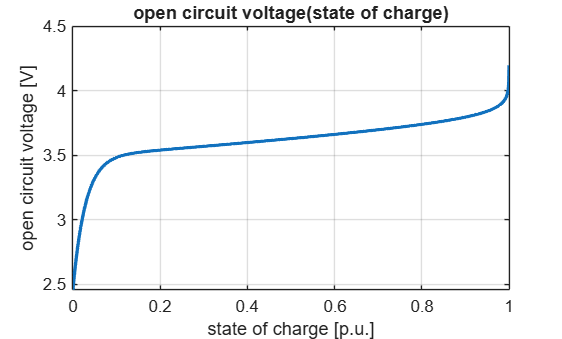

typical_cell_voltage = 3.6;
number_of_cells = floor(ubattery/typical_cell_voltage)-1; % nominal is 100

% stato of charge init
soc_init = 0.85; 

R = 8.3143;
F = 96487;
T = 273.15+40;
Q = 50; %Hr*A

Vbattery_nom = ubattery;
Pbattery_nom = Pnom;
Ibattery_nom = Pbattery_nom/Vbattery_nom;
Rmax = Vbattery_nom^2/(Pbattery_nom*0.1);
Rmin = Vbattery_nom^2/(Pbattery_nom);

E_1 = -1.031;
E0 = 3.485;
E1 = 0.2156;
E2 = 0;
E3 = 0;
Elog = -0.05;
alpha = 35;

R0 = 0.0035;
R1 = 0.0035;
C1 = 0.5;
M = 125;

q1Kalman = ts_inv^2;
q2Kalman = ts_inv^1;
q3Kalman = 0;
rKalman = 1;

Zmodel = (0:1e-3:1);
ocv_model = E_1*exp(-Zmodel*alpha) + E0 + E1*Zmodel + E2*Zmodel.^2 +...
    E3*Zmodel.^3 + Elog*log(1-Zmodel+ts_inv);
figure; 
plot(Zmodel,ocv_model,'LineWidth',2);
xlabel('state of charge [p.u.]');
ylabel('open circuit voltage [V]');
title('open circuit voltage(state of charge)');
grid on

## IGBT and snubber data

### HeatSink

weigth = 0.50; % kg
cp_al = 880; % J/K/kg
heat_capacity = cp_al*weigth % J/K

heat_capacity =    440

thermal_conducibility = 204; % W/(m K)
Rth_mosfet_HA = 30/1000 % K/W

Rth_mosfet_HA =      3.000000000000000e-02

Tambient = 40;
DThs_init = 0;

### SKM1700MB20R4S2I4

Ron = 1.04e-3; % Rds [Ohm]
Vdon_diode = 4; % V
Vgamma = 4; % V
Rdon_diode = 1.85e-3; % V
Eon = 77e-3; % J @ Tj = 125°C
Eoff = 108e-3; % J @ Tj = 125°C
Eerr = 9.7e-3; % J @ Tj = 125°C
Voff_sw_losses = 1500; % V
Ion_sw_losses = 2000; % A

JunctionTermalMass = 5; % J/K
Rtim = 0.05;
Rth_mosfet_JC = 19/1000; % K/W
Rth_mosfet_CH = 6/1000; % K/W
Rth_mosfet_JH = Rtim + Rth_mosfet_JC + Rth_mosfet_CH % K/W

Rth_mosfet_JH =      7.500000000000001e-02

Lstray_module = 12e-9;

Irr = 475;
Csnubber = Irr^2*Lstray_module/Vdc_nom^2

Csnubber =      9.284979423868312e-09

Rsnubber = 1/(Csnubber*fPWM_INV)/5

Rsnubber =      2.154016620498615e+03

### FF1000UXTR23T2M1


% Ron = 2.13e-3; % Rds [Ohm]
% Vgamma = 5.5; % V
% Eon = 540e-3; % J @ Tj = 125°C
% Eoff = 370e-3; % J @ Tj = 125°C
% Eerr = 0.075e-3; % J @ Tj = 125°C
% Voff_sw_losses = 1500; % V
% Ion_sw_losses = 2000; % A
% 
% JunctionTermalMass = 0.025; % J/K
% Rtim = 0.05;
% Rth_mosfet_JC = 20/1000; % K/W
% Rth_mosfet_CH = 5.8/1000; % K/W
% Rth_mosfet_JH = Rtim + Rth_mosfet_JC + Rth_mosfet_CH % K/W

## C-Caller Settings

model = 'single_phase_inverter';
open_system(model);
% Simulink.importExternalCTypes(model,'Names',{'mavgflt_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'bemf_obsv_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'bemf_obsv_load_est_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'dqvector_pi_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'sv_pwm_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'global_state_machine_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'first_harmonic_tracker_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'dqpll_thyr_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'dqpll_grid_output_t'});

## Remove Scopes Opening Automatically

open_scopes = find_system(model, 'BlockType', 'Scope');
for i = 1:length(open_scopes)
    set_param(open_scopes{i}, 'Open', 'off');
end

% shh = get(0,'ShowHiddenHandles');
% set(0,'ShowHiddenHandles','On');
% hscope = findobj(0,'Type','Figure','Tag','SIMULINK_SIMSCOPE_FIGURE');
% close(hscope);
% set(0,'ShowHiddenHandles',shh);
